# World's Tallest Buildings - Distributions

## 1.

Load `tallest_bldgs.mat`.

load tallest_bldgs
%  Extract heights
x = buildings.Height_m

## 2.

Make a histogram of building heights (in meters) using bins from 200 to 820 m, in 20 m increments.

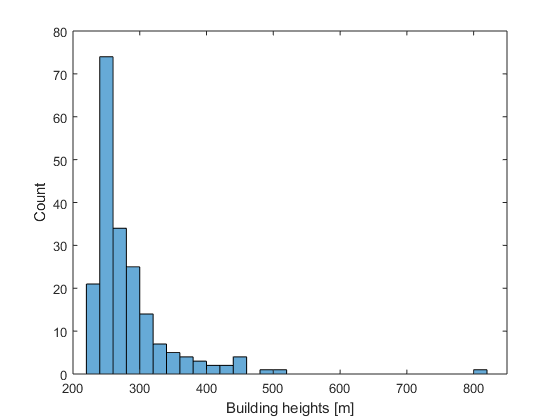

h = 200:20:820;
histogram(x,h)
xlim([200,850])
xlabel('Building heights [m]')
ylabel('Count')

## 3.

The distribution appears to show an inverse relationship between the height and the number of buildings with that height. This may indicate that the building height follows a Pareto distribution, which is the formal mathematical expression of the commonly cited “80-20 law”. The Pareto distribution is closely related to the exponential distribution.  If $x$ comes from a Pareto distribution, then $y = ln(x/x_{min})$, where $x_{min}$ is the minimum value of $x$, comes from an exponential distribution. To determine if building height is Pareto distributed, calculate a transformed version, according to the above formula.

xmn = min(x);
y = log(x/xmn)

y =     1.2383
    0.6233
    0.6122
    0.4742
    0.7645
    0.7297
    0.3706
    0.5600
    0.2257
    0.6451


## 4.

Create exponential probability plots of both the raw and transformed height data. Does either appear to be exponentially distributed?

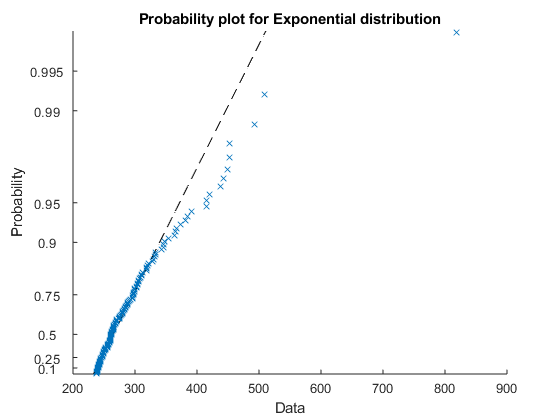

figure
probplot('exponential',x)

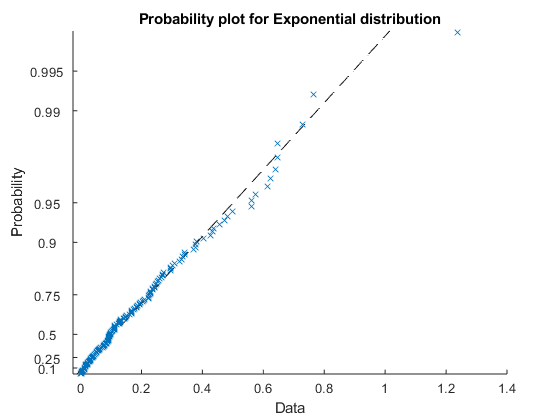

%  No
figure
probplot('exponential',y)

%  Yes

## 5.

A Pareto distribution is defined by two parameters, $x_{min}$, which can be easily estimated from the data, and a shape parameter $\alpha$.  An exponential distribution is defined by a single parameter $\mu$.  After transforming a Pareto distribution to an exponential distribution, the parameters are related by $\alpha = \frac{1}{\mu}$.  Fit an exponential distribution to the transformed data.  From this fit, determine the Pareto shape parameter $\alpha$.

efit = fitdist(y,'exponential')

efit =   ExponentialDistribution

  Exponential distribution
    mu = 0.159837   [0.139716, 0.184664]


alpha = 1/efit.Params

alpha = 6.2564

## 6.

Using `histogram`, create an approximate pdf of the heights. Overlay the theoretical Pareto pdf, using the parameters found above, and the formula


$$\rho(x)=\frac{\alpha x_{min}^{\alpha}}{x^{\alpha+1}}$$


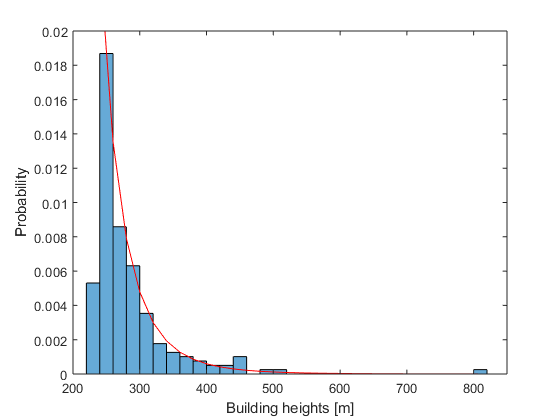

histogram(x,h,'Normalization','pdf')
hold on
parpdf = alpha*xmn^alpha./h.^(alpha+1);
plot(h,parpdf,'r')
hold off
axis([200,850,0,0.02])
xlabel('Building heights [m]')
ylabel('Probability')